close
clear
clc
s = tf('s');

## Initializing

eta_g = 0.9;
K_g = 70;
r = eta_g*K_g;
eta_m = 0.69;
K_t = 0.00767;
K_m = 0.00767;
K_stiff = 1.2485;
R_m = 2.6;
J_arm = 0.0035;
J_hub = 0.0026;
J_eq = 0.00208;
B_eq = 0.004;
m_1 = 0.064;
m_2 = 0.030;
L_1 = 0.298;
L_2 = 0.156;

## A

A11 = zeros(2);
A12 = eye(2);
A21 = [0                 inv(J_hub)*K_stiff;
       0 -(inv(J_hub) + inv(J_arm))*K_stiff;];
A22 = [-inv(J_hub)*(((r*eta_m*K_t*K_m)/R_m) + B_eq) 0;
       +inv(J_hub)*(((r*eta_m*K_t*K_m)/R_m) + B_eq) 0];
A = [A11 A12;
     A21 A22];
display(A)

A =          0         0    1.0000         0
         0         0         0    1.0000
         0  480.1923   -1.9168         0
         0 -836.9066    1.9168         0


## Poles

sys_p = eig(A);
display(sys_p)

sys_p =    0.0000 + 0.0000i
  -0.5495 +28.9086i
  -0.5495 -28.9086i
  -0.8179 + 0.0000i


## B

B = ((r*eta_m*K_t*K_m)/(J_hub*R_m))*[0;
                                     0;
                                     1;
                                    -1];
display(B)

B =          0
         0
    0.3783
   -0.3783


## C

C = [eye(2) zeros(2)];
display(C)

C =      1     0     0     0
     0     1     0     0


## D and U

D = [0;
     0];
display(D)

D =      0
     0


U = 1;
display(U)

U = 1

## Transfer Function

[Num , Den] = ss2tf(A, B, C, D);
display(Num), display(Den)

Num =          0         0    0.3783         0  134.9442
         0         0   -0.3783   -0.0000   -0.0000


Den =     1.0000    1.9168  836.9066  683.7354         0


G_theta = tf(Num(1,:), Den);
G_theta_pole = pole(G_theta);
G_alfa = tf(Num(2,:), Den);
G_alfa_pole = pole(G_alfa);
display(G_theta), display(G_theta_pole)

G_theta =
 
           0.3783 s^2 + 134.9
  -------------------------------------
  s^4 + 1.917 s^3 + 836.9 s^2 + 683.7 s
 
Continuous-time transfer function.



G_theta_pole =    0.0000 + 0.0000i
  -0.5495 +28.9086i
  -0.5495 -28.9086i
  -0.8179 + 0.0000i


display(G_alfa), display(G_alfa_pole)

G_alfa =
 
  -0.3783 s^2 - 1.68e-16 s - 1.545e-32
  -------------------------------------
  s^4 + 1.917 s^3 + 836.9 s^2 + 683.7 s
 
Continuous-time transfer function.



G_alfa_pole =    0.0000 + 0.0000i
  -0.5495 +28.9086i
  -0.5495 -28.9086i
  -0.8179 + 0.0000i


## Controlability Check

C_c = ctrb(A, B);
C_c_rank = rank(C_c);
if C_c_rank == length(A)
    disp("It is controlable!"), disp(C_c_rank)
else
    disp("It is not controlable!"), display(C_c_rank), display(length(A))
end

It is controlable!
     4



## Controller

K_ctrl = 1;
p = 1;
z = 1;
alfa = p / z;
G_ctrl = alfa * (s + z) / (s + p);

## K as Gain

K_v = Num(9) / Den(4);
K_ctrl = 10 / K_v;
display(K_v), display(K_ctrl)

K_v = 0.1974

K_ctrl = 50.6680

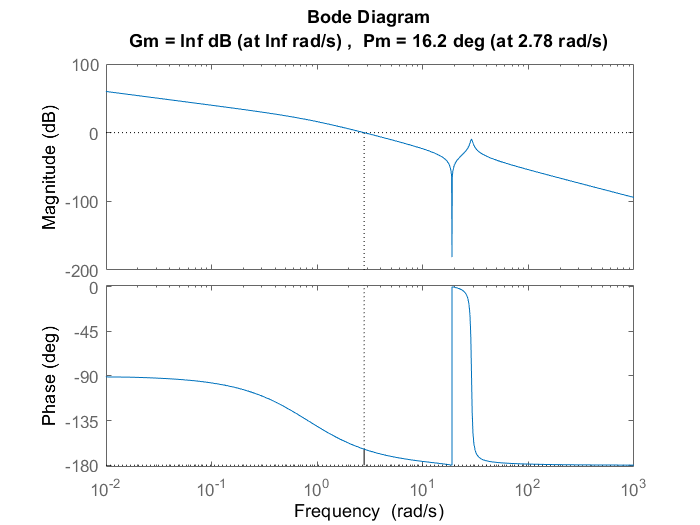

margin(K_ctrl*G_theta)

alfa = (2+sqrt(3))/(2-sqrt(3))

alfa = 13.9282

w_m = 1.55

w_m = 1.5500

p = sqrt(alfa * w_m^2)

p = 5.7847

z = p / alfa

z = 0.4153

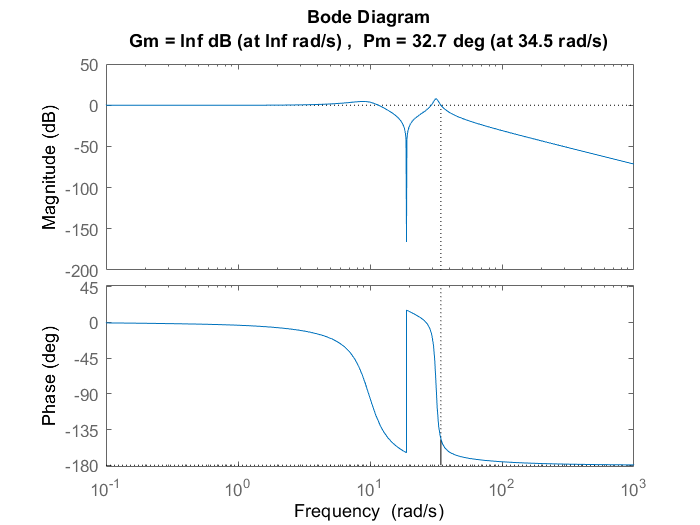

T_ol = K_ctrl * alfa * ((s+z)/(s+p)) * G_theta;
T_cl = feedback(T_ol, 1);
margin(T_cl)